## Ensemble DRL Training

clear;
close all;
bdclose('all');
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/model')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/DRL_training/trained_agent')
addpath('/home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC')

## Environment Setup

Ts = 0.1;           % simulation time step in sec
Ts_data = Ts;      % time step to collect data in sec
T = 30;             % simulation time
D_default = 10;     % default distance
v_set = 30;         % driver-set velocity for ego car
t_gap = 1.4;        % time gap to calculate safe distance
vmin_lead = 2;      % lead car minimum velocity
      
vmax_ego = 50;      % ego car minimum/maximum velocity
vmin_ego = -50;

amin_ego = -3;      % ego car minimum/maximum acceleration
amax_ego = 2;       

x0_lead = 70;       % lead car initial velocity and position
v0_lead = 30;
a_lead_seed = 0;    % seed to generate random input a_lead

x0_ego = 10;        % ego car initial velocity and position
v0_ego = 25;

amin_lead = -1;     % lead car minimum/maximum acceleration
amax_lead = 1;

rewardDim = 2;       % reward dimension [distanceReward, velocityReward]
isTerminate = false;

% input to simulink: take a_lead from a uniform distribution
change_freq = 2;    % input signal change value every change_freq sec

## Load Constitutional Controllers

% load trained RL controllers

rlAgent1 = load("ACC-DDPG-03-May-0.2-0.8-0.01").saveAgent;
rlAgent2 = load("ACC-DDPG-29-Apr-0.5-0.5-0.01").saveAgent;
rlAgent3 = load("ACC-DDPG-29-Apr-0.8-0.2-0.01").saveAgent;
rlAgent4 = load("ACC-SAC-02-May-0.3-0.7-0.1").saveAgent;
rlAgent5 = load("ACC-SAC-02-May-0.5-0.5-0.01").saveAgent;
rlAgent6 = load("ACC-SAC-02-May-0.8-0.2-0.01").saveAgent;
rlAgent7 = load("ACC-TD3-03-May-0.2-0.8-0.01").saveAgent;
rlAgent8 = load("ACC-TD3-03-May-0.5-0.5-0.01").saveAgent;
rlAgent9 = load("ACC-TD3-03-May-0.8-0.2-0.01").saveAgent;

agent1 = rlAgent1.agent;
agent2 = rlAgent2.agent;
agent3 = rlAgent3.agent;
agent4 = rlAgent4.agent;
agent5 = rlAgent5.agent;
agent6 = rlAgent6.agent;
agent7 = rlAgent7.agent;
agent8 = rlAgent8.agent;
agent9 = rlAgent9.agent;

% reward from constitutional RL agents
rewardWeights = [rlAgent1.rewardWeights;
                rlAgent2.rewardWeights;
                rlAgent3.rewardWeights;
                rlAgent4.rewardWeights;
                rlAgent5.rewardWeights;
                rlAgent6.rewardWeights;
                rlAgent7.rewardWeights;
                rlAgent8.rewardWeights;
                rlAgent9.rewardWeights];

numRL = length(rewardWeights);      % num of RL controllers

% load MPC controllers
MPC_PH_1 = 5;
MPC_behavior_1 = 0;
MPC_PH_2 = 50;
MPC_behavior_2 = 1;
MPC_ST = Ts;

numController = 9;

% load abstracted MDP
abstractMDP = load("ACC_abstract_model").abModel;
actionUB = abstractMDP.actionUB;
rewardUB1 = abstractMDP.rewardUB_1;
rewardUB2 = abstractMDP.rewardUB_2;
rewardToIndex = abstractMDP.rewardToIndexTable;
tranTable = abstractMDP.tranTable;

## DRL Obs/Act configuration

Creating an environment model includes action, obervation

**Observation**: 

- Target velocity: v_set or v_lead

- Ego car velocity

- Relative distance

- Relative velocity

- Safety distance

- -> 10. transition reward predictions

**Action**: Selection of constitutional controllers

% observation
obsInfo = rlNumericSpec([14 1],...
    'LowerLimit', -inf*ones(14,1),...
    'UpperLimit', inf*ones(14,1));
obIsnfo.Name = 'observation';
obsInfo.Description = 'v_target, v_rel, v_ego, d_safe, d_rel, prediction*9';
numObservations = obsInfo.Dimension(1);

% action
actInfo = rlFiniteSetSpec([1 2 3 4 5 6 7 8 9]);
actInfo.Name = 'controller selection';
numActions = actInfo.Dimension(1);

mdl = 'ACC_ensemble_training';
agentblk = [mdl, '/Ensemble Control System/ensemble_RL'];

% Build the environment interface object.
env = rlSimulinkEnv(mdl,agentblk,obsInfo,actInfo);

% Fix the random generator seed for reproducibility
% rng(0);

## DRL Agent Configuration

[https://www.mathworks.com/help/reinforcement-learning/ref/rltrpoagent.html#mw_f0de91f0-5454-49c6-91a0-5d61f0563a10](https://www.mathworks.com/help/reinforcement-learning/ref/rltrpoagent.html#mw_f0de91f0-5454-49c6-91a0-5d61f0563a10)

**Create a network to be used as underlying critic approximator**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlvaluefunction.html](https://www.mathworks.com/help/reinforcement-learning/ref/rlvaluefunction.html)

criticNetwork = [
    featureInputLayer(numObservations,'Normalization','none','Name','observation')
    fullyConnectedLayer(32,'Name','CriticStateFC1')
    reluLayer('Name','CriticRelu1')
    fullyConnectedLayer(64,'Name','CriticStateFC2')
    reluLayer('Name','CriticCommonRelu1')
    fullyConnectedLayer(128,'Name','CriticCommonFC1')
    reluLayer('Name','CriticCommonRelu2')
    fullyConnectedLayer(64,'Name','CriticCommonFC2')
    reluLayer('Name','CriticCommonRelu3')
    fullyConnectedLayer(32,'Name','CriticCommonFC3')
    reluLayer('Name','CriticCommonRelu4')
    fullyConnectedLayer(1,'Name','CriticOutput')];

% convert the network to a dlnetwork object
criticNetwork = dlnetwork(criticNetwork);

% create critic based on the network approximator
critic = rlValueFunction(criticNetwork,obsInfo,'UseDevice','cpu');

**Create a network to be used as underlying actor approximator**

[https://www.mathworks.com/help/reinforcement-learning/ref/rldiscretecategoricalactor.html](https://www.mathworks.com/help/reinforcement-learning/ref/rldiscretecategoricalactor.html)

actorNetwork = [
    featureInputLayer(prod(obsInfo.Dimension),'Normalization','none','Name','observation')
    fullyConnectedLayer(64,'Name','ActorFC1')
    reluLayer('Name','ActorRelu1')
    fullyConnectedLayer(128,'Name','ActorFC2')
    reluLayer('Name','ActorRelu2')
    fullyConnectedLayer(length(actInfo.Elements),'Name','ActorFC3')                       
    softmaxLayer('Name','actionProb')];

actor  = rlDiscreteCategoricalActor(actorNetwork,obsInfo,actInfo);

**DRL agent options**

[https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagentoptions.html](https://www.mathworks.com/help/reinforcement-learning/ref/rlddpgagentoptions.html)

**Noise model:**

- It is common to set `StandardDeviation*sqrt(Ts)` to a value between 1% and 10% of your action rang. **[0.158, 1.58]**

- To increase exploration, you can reduce the `StandardDeviationDecayRate`.

% Optimization options for actors and critics
myCriticOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

myActorOpts=rlOptimizerOptions(...
    'LearnRate',1e-4,...
    'GradientThreshold',1,...
    'GradientThresholdMethod',"l2norm",...
    'L2RegularizationFactor', 1e-4,...
    'Optimizer',"adam");

% Options for SAC agent
% agentOptions = rlTRPOAgentOptions(...
%     'CriticOptimizerOptions', myCriticOpts,...
%     'SampleTime',Ts,...
%     'MiniBatchSize',128,...
%     'DiscountFactor',0.99);

agentOptions = rlACAgentOptions(...
    'CriticOptimizerOptions', myCriticOpts,...
    'ActorOptimizerOptions',myActorOpts,...
    'SampleTime',Ts,...
    'NumStepsToLookAhead',5,...
    'EntropyLossWeight',0.01,...
    'DiscountFactor',0.99);

% agent creation
% agentEnsemble = rlTRPOAgent(actor, critic, agentOptions);
agentEnsemble = rlACAgent(actor, critic, agentOptions);

## **Training Configurations**

Change the weights distribution among subsitutional rewards

maxepisodes = 5000; 
maxsteps = ceil(T/Ts);
windowLength = 20;

% change reward weights distribution
ensembleRewardWeights = [0.7, 0.3, 0.05];

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', maxepisodes, ...
    'MaxStepsPerEpisode', maxsteps, ...
    'ScoreAveragingWindowLength',windowLength, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue', sum(ensembleRewardWeights)*maxsteps*0.95,...
    'SaveAgentCriteria','AverageReward',...
    'SaveAgentValue', sum(ensembleRewardWeights)*maxsteps*0.9,...
    'Verbose', false,...
    'Plots','training-progress',...
    'UseParallel',false);

doTraining = true;

if doTraining
    % Train the agent.
    isEnsembleTerminate = true;
    trainingStats = train(agentEnsemble,env,trainOpts);
else
%     agent = load('preTrainedAgent.mat');
%     agent = agent.agent;
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = true;

if isSave
    dateOfTrain = date;
    agentName = ['ACC-ensemble-AC-9-RL-0-MPC-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(ensembleRewardWeights(1))+...
        "-"+string(ensembleRewardWeights(2))+...
        "-"+string(ensembleRewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agentEnsemble, ...
                 'rewardWeights', ensembleRewardWeights, ...
                 'ensembleController',[rlAgent1.agentName; rlAgent2.agentName; ...3
                                        rlAgent3.agentName;rlAgent4.agentName;rlAgent5.agentName],...
                 'ensembleMPC',[],...
                 'trainingStats', trainingStats, ...
                 'agentOptions', agentOptions, ...
                 'criticNetwork', criticNetwork, ...
                 'actorNetwork', actorNetwork, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/ACC/ensemble_train/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

ACC-ensemble-AC-9-RL-0-MPC-30-May-0.7-0.3-0.05 saved


## Simulation & Plotting

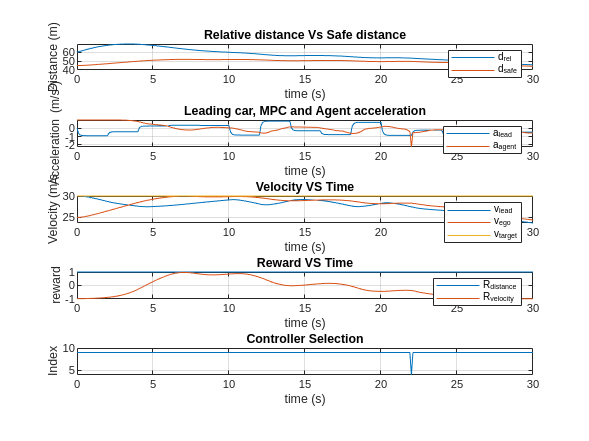

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agentEnsemble,simOpts);
totalReward = sum(experiences.Reward);

% extract signals from simulation results
time = experiences.SimulationInfo.tout;
steps = size(time);
steps = steps(1);
d_safe = experiences.SimulationInfo.logsout.getElement('d_safe').Values.Data;
d_safe = reshape(d_safe, [steps,1]);
d_rel = experiences.SimulationInfo.logsout.getElement('d_rel').Values.Data;
d_rel = reshape(d_rel, [steps,1]);
final_action = experiences.SimulationInfo.logsout.getElement('final_action').Values.Data;
final_action = reshape(final_action, [steps,1]);
a_lead = experiences.SimulationInfo.logsout.getElement('a_lead').Values.Data;
a_lead = reshape(a_lead, [steps,1]);
v_lead = experiences.SimulationInfo.logsout.getElement('v_lead').Values.Data;
v_lead = reshape(v_lead, [steps,1]);
v_ego = experiences.SimulationInfo.logsout.getElement('v_ego').Values.Data;
v_ego = reshape(v_ego, [steps,1]);
selection = experiences.SimulationInfo.logsout.getElement('selection').Values.Data;
selection = reshape(selection, [steps,1]);
v_target =  experiences.SimulationInfo.logsout.getElement('v_target').Values.Data;
v_target = reshape(v_target, [steps,1]);
d_reward = experiences.SimulationInfo.logsout.getElement('d_reward').Values.Data;
d_reward = reshape(d_reward, [steps,1]);
v_reward = experiences.SimulationInfo.logsout.getElement('v_reward').Values.Data;
v_reward = reshape(v_reward, [steps,1]);
% all_reward = experiences.SimulationInfo.logsout.getElement('all_reward').Values.Data;
% all_reward = reshape(all_reward, [steps,1]);

% plotting
figure(1);
subplot(5,1,1);
plot(time,d_rel, time, d_safe);
title('Relative distance Vs Safe distance');
legend('d_{rel}','d_{safe}');
xlabel('time (s)') ;
ylabel('Distance (m)') ;
grid on;

subplot(5,1,2);
plot(time,a_lead, time,final_action);
title('Leading car, MPC and Agent acceleration');
legend('a_{lead}', 'a_{agent}');
xlabel('time (s)') ;
ylabel('Acceleration (m/s^{2})') ;
grid on;

subplot(5,1,3);
plot(time,v_lead, time, v_ego, time,v_target);
title('Velocity VS Time');
legend('v_{lead}','v_{ego}','v_{target}');
xlabel('time (s)') ;
ylabel('Velocity (m/s') ;
grid on;

subplot(5,1,4);
plot(time,d_reward, time, v_reward);
title('Reward VS Time');
legend('R_{distance}', 'R_{velocity}');
xlabel('time (s)') ;
ylabel('reward') ;
grid on;

subplot(5,1,5);
plot(time,selection);
title('Controller Selection');
xlabel('time (s)') ;
ylabel('Index') ;
grid on;

## Training progress info

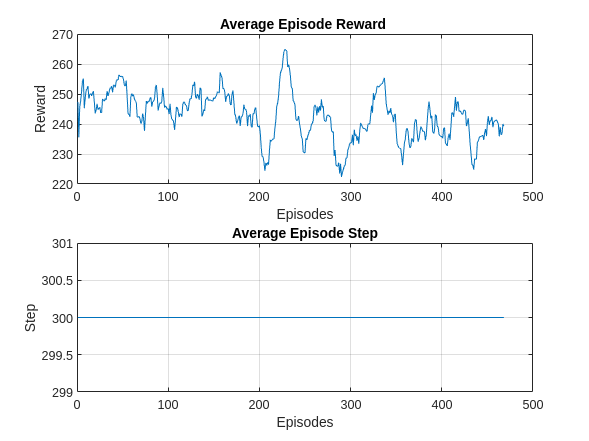

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(2);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on

## Reset function

Randomized initial positions and velocities of ego and lead cars

function in = localResetFcn(in)
    % reset
    in = setVariable(in,'v_set', 25+randi(10,1,1));           % random value for user-set velocity
%     in = setVariable(in,'a_lead_seed', randi(10000));   % random value for a_lead generator seed
%     in = setVariable(in,'x0_lead', 60+randi(40,1,1));    % random value for lead car initial position
%     in = setVariable(in,'v0_lead', 20+randi(15,1,1));    % random value for lead car initial velocity
end


